%% EXAMEN PARCIAL - ROBÓTICA
% Estudiante: José Luis Raya Cruz  
% Fecha: 20 de Octubre de 2025
% Universidad: Facultad de Ingeniería, UNAM
% Asignatura: Robótica

clear all
close all
clc

fprintf('========================================\n');

fprintf('EXAMEN PARCIAL - MODELADO DE ROBOT SCARA\n'); 

EXAMEN PARCIAL - MODELADO DE ROBOT SCARA


fprintf('========================================\n\n');

## 1. INTRODUCCIÓN

fprintf('---------------\n');
fprintf('1. INTRODUCCIÓN\n');

1. INTRODUCCIÓN


fprintf('---------------\n');

---------------



fprintf('El presente examen da la evidencia del dominio adquirido de los contenidos vistos de la asignatura de Robótica. Su propósito fundamental reside en demostrar la capacidad de aplicar los principios teóricos al análisis completo de un sistema robótico real, específicamente un manipulador SCARA.\n\n');

El presente examen da la evidencia del dominio adquirido de los contenidos vistos de la asignatura de Robótica. Su propósito fundamental reside en demostrar la capacidad de aplicar los principios teóricos al análisis completo de un sistema robótico real, específicamente un manipulador SCARA.



fprintf('La importancia de este trabajo va al conocimiento académico, pues el modelado cinemático y dinámico representa la base sobre la cual se sustentan las aplicaciones que esta pueden servirnos en algún futuro. Cada sección desarrollada corresponde a la metodología expuesta durante las sesiones de clase.\n\n');

La importancia de este trabajo va al conocimiento académico, pues el modelado cinemático y dinámico representa la base sobre la cual se sustentan las aplicaciones que esta pueden servirnos en algún futuro. Cada sección desarrollada corresponde a la metodología expuesta durante las sesiones de clase.




%% DIAGRAMA DEL ROBOT SCARA
fprintf('DIAGRAMA ESQUEMÁTICO DEL ROBOT SCARA\n');

DIAGRAMA ESQUEMÁTICO DEL ROBOT SCARA


fprintf('------------------------------------\n');

------------------------------------



fprintf('Configuración mecánica del robot objeto de estudio:\n\n');

Configuración mecánica del robot objeto de estudio:



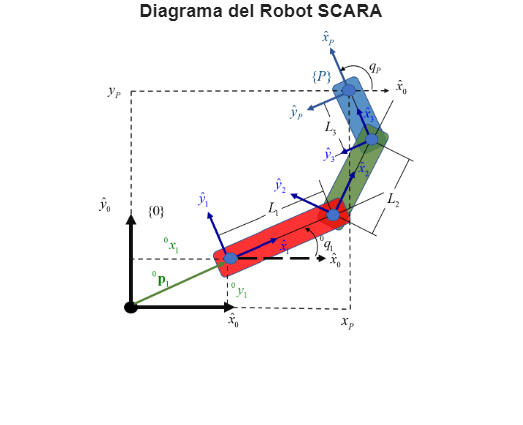


%% DIAGRAMA DEL ROBOT SCARA
figure; % crea una nueva ventana
imshow('Modelo.png'); % muestra la imagen
title('Diagrama del Robot SCARA');



fprintf('Especificaciones técnicas:\n');

Especificaciones técnicas:


fprintf('- Arquitectura: SCARA (Selective Compliance Assembly Robot Arm)\n');

- Arquitectura: SCARA (Selective Compliance Assembly Robot Arm)


fprintf('- Grados de libertad: 3 (rotacionales)\n');

- Grados de libertad: 3 (rotacionales)


fprintf('- Espacio de trabajo: Planar con capacidad de posicionamiento preciso\n');

- Espacio de trabajo: Planar con capacidad de posicionamiento preciso


fprintf('- Aplicaciones típicas: Ensamble, pick-and-place, manufactura\n\n');

- Aplicaciones típicas: Ensamble, pick-and-place, manufactura



## 2. DEFINICIÓN DE VARIABLES SIMBÓLICAS

fprintf('-------------------------------------\n');
fprintf('2. DEFINICIÓN DE VARIABLES SIMBÓLICAS\n');

2. DEFINICIÓN DE VARIABLES SIMBÓLICAS


fprintf('-------------------------------------\n');

-------------------------------------



fprintf('El abordaje metodológico inicia con la formalización matemática del sistema mediante la definición de variables simbólicas que representan los parámetros físicos y estados del robot.\n\n');

El abordaje metodológico inicia con la formalización matemática del sistema mediante la definición de variables simbólicas que representan los parámetros físicos y estados del robot.




% Variables articulares
syms theta_0_1 theta_1_2 theta_2_3 real
fprintf('Variables articulares:\n');

VARIABLES ARTICULARES:


fprintf('Estas variables definen la configuración instantánea del manipulador:\n\n');

Estas variables definen la configuración instantánea del manipulador:



fprintf('- theta_0_1: Desplazamiento angular de la articulación base\n');

- theta_0_1: Desplazamiento angular de la articulación base


fprintf('- theta_1_2: Desplazamiento angular de la articulación intermedia\n');

- theta_1_2: Desplazamiento angular de la articulación intermedia


fprintf('- theta_2_3: Desplazamiento angular de la articulación final\n\n');

- theta_2_3: Desplazamiento angular de la articulación final




% Velocidades articulares
syms theta_dot_0_1 theta_dot_1_2 theta_dot_2_3 real
fprintf('Velocidades articulares:\n');

VELOCIDADES ARTICULARES:


fprintf('Representan las derivadas temporales de las variables articulares:\n\n');

Representan las derivadas temporales de las variables articulares:



fprintf('- theta_dot_0_1: Velocidad angular de la articulación base\n');

- theta_dot_0_1: Velocidad angular de la articulación base


fprintf('- theta_dot_1_2: Velocidad angular de la articulación intermedia\n');

- theta_dot_1_2: Velocidad angular de la articulación intermedia


fprintf('- theta_dot_2_3: Velocidad angular de la articulación final\n\n');

- theta_dot_2_3: Velocidad angular de la articulación final




% Aceleraciones articulares
syms theta_ddot_0_1 theta_ddot_1_2 theta_ddot_2_3 real
fprintf('Aceleraciones articulares:\n');

ACELERACIONES ARTICULARES:


fprintf('Corresponden a las segundas derivadas temporales:\n\n');

Corresponden a las segundas derivadas temporales:



fprintf('- theta_ddot_0_1: Aceleración angular de la articulación base\n');

- theta_ddot_0_1: Aceleración angular de la articulación base


fprintf('- theta_ddot_1_2: Aceleración angular de la articulación intermedia\n');

- theta_ddot_1_2: Aceleración angular de la articulación intermedia


fprintf('- theta_ddot_2_3: Aceleración angular de la articulación final\n\n');

- theta_ddot_2_3: Aceleración angular de la articulación final




% Parámetros geométricos del robot
syms L_1 L_2 L_3 real
syms x_0_1 y_0_1 real

fprintf('Parámetros geométricos:\n');

PARÁMETROS GEOMÉTRICOS:


fprintf('Definen la estructura física del manipulador:\n\n');

Definen la estructura física del manipulador:



fprintf('- L_1 = 0.3 m: Longitud del eslabón proximal\n');

- L_1 = 0.3 m: Longitud del eslabón proximal


fprintf('- L_2 = 0.25 m: Longitud del eslabón intermedio\n');

- L_2 = 0.25 m: Longitud del eslabón intermedio


fprintf('- L_3 = 0.2 m: Longitud del eslabón final\n');

- L_3 = 0.2 m: Longitud del eslabón final


fprintf('- x_0_1, y_0_1: Coordenadas de localización de la base\n\n');

- x_0_1, y_0_1: Coordenadas de localización de la base




fprintf('La selección de estas variables se fundamenta en la necesidad de representar completamente el estado mecánico del sistema para su análisis y subtemas posteriores.\n\n');

La selección de estas variables se fundamenta en la necesidad de representar completamente el estado mecánico del sistema para su análisis y subtemas posteriores.



## 3. MODELADO CINEMÁTICO DE LA POSTURA

fprintf('------------------------------------\n');
fprintf('3. MODELADO CINEMÁTICO DE LA POSTURA\n');

3. MODELADO CINEMÁTICO DE LA POSTURA


fprintf('------------------------------------\n');

------------------------------------



fprintf('El modelado cinemático establece la relación entre las coordenadas articulares y la "posición/orientación" del extremo final en el espacio cartesiano, sin considerar las fuerzas que generan el movimiento.\n\n');

El modelado cinemático establece la relación entre las coordenadas articulares y la "posición/orientación" del extremo final en el espacio cartesiano, sin considerar las fuerzas que generan el movimiento.




%% 3.1 TRANSFORMACIONES HOMOGÉNEAS
fprintf('-------------------------------\n');
fprintf('3.1 Transformaciones homogéneas\n');

3.1 TRANSFORMACIONES HOMOGÉNEAS


fprintf('-------------------------------\n');

-------------------------------



fprintf('Las transformaciones homogéneas permiten describir sistemáticamente la relación espacial entre sistemas de referencia consecutivos:\n\n');

Las transformaciones homogéneas permiten describir sistemáticamente la relación espacial entre sistemas de referencia consecutivos:




fprintf('Cadena cinemática completa:\n');

Cadena cinemática completa:


fprintf('     T_0_1        T_1_2        T_2_3        T_3_P\n');

     T_0_1        T_1_2        T_2_3        T_3_P


fprintf('S₀ ────────> S₁ ────────> S₂ ────────> S₃ ────────> P\n');

S₀ ────────> S₁ ────────> S₂ ────────> S₃ ────────> P


fprintf('   [x₀,y₀]       [θ₁]         [θ₂]         [θ₃]  [x,y,φ]\n\n');

   [x₀,y₀]       [θ₁]         [θ₂]         [θ₃]  [x,y,φ]




% Transformación del sistema 0 al sistema 1
fprintf('a) Transformación T_0_1 - Sistema base a primera articulación:\n');

a) Transformación T_0_1 - Sistema base a primera articulación:


fprintf('Establece la relación entre el sistema de referencia base y la primera articulación.\n');

Establece la relación entre el sistema de referencia base y la primera articulación.



T_0_1 = [cos(theta_0_1), -sin(theta_0_1), 0, x_0_1;
         sin(theta_0_1),  cos(theta_0_1), 0, y_0_1;
         0,               0,              1, 0;
         0,               0,              0, 1];

fprintf('T_0_1 = \n');

T_0_1 = 


disp(T_0_1);

$$\left(\begin{array}{cccc} \cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & 0 & x_{0,1}\\ \sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & 0 & y_{0,1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

fprintf('\n');

fprintf('Análisis de la transformación:\n');

Análisis de la transformación:


fprintf('- Submatriz de rotación: Define la orientación relativa\n');

- Submatriz de rotación: Define la orientación relativa


fprintf('- Vector de traslación: Especifica la posición relativa\n');

- Vector de traslación: Especifica la posición relativa


fprintf('- Configuración planar: Conserva la coordenada Z constante\n\n');

- Configuración planar: Conserva la coordenada Z constante




% Transformación del sistema 1 al sistema 2
fprintf('b) Transformación T_1_2 - Primera a segunda articulación:\n');

b) Transformación T_1_2 - Primera a segunda articulación:



T_1_2 = [cos(theta_1_2), -sin(theta_1_2), 0, L_1;
         sin(theta_1_2),  cos(theta_1_2), 0, 0;
         0,               0,              1, 0;
         0,               0,              0, 1];

fprintf('T_1_2 = \n');

T_1_2 = 


disp(T_1_2);

$$\left(\begin{array}{cccc} \cos\left(\theta_{1,2}\right) & -\sin\left(\theta_{1,2}\right) & 0 & L_{1}\\ \sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

fprintf('\n');

% Transformación del sistema 2 al sistema 3
fprintf('c) Transformación T_2_3 - Segunda a tercera articulación:\n');

c) Transformación T_2_3 - Segunda a tercera articulación:



T_2_3 = [cos(theta_2_3), -sin(theta_2_3), 0, L_2;
         sin(theta_2_3),  cos(theta_2_3), 0, 0;
         0,               0,              1, 0;
         0,               0,              0, 1];

fprintf('T_2_3 = \n');

T_2_3 = 


disp(T_2_3);

$$\left(\begin{array}{cccc} \cos\left(\theta_{2,3}\right) & -\sin\left(\theta_{2,3}\right) & 0 & L_{2}\\ \sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

fprintf('\n');

% Transformación del sistema 3 al extremo final
fprintf('d) Transformación T_3_P - Tercera articulación al extremo final:\n');

d) Transformación T_3_P - Tercera articulación al extremo final:



T_3_P = [1, 0, 0, L_3;
         0, 1, 0, 0;
         0, 0, 1, 0;
         0, 0, 0, 1];

fprintf('T_3_P = \n');

T_3_P = 


disp(T_3_P);

$$\left(\begin{array}{cccc} 1 & 0 & 0 & L_{3}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

fprintf('\n');

fprintf('Características de las transformaciones:\n');

Características de las transformaciones:


fprintf('- Consistencia con la convención Denavit-Hartenberg\n');

- Consistencia con la convención Denavit-Hartenberg


fprintf('- Preservación de la ortogonalidad de los sistemas de referencia\n');

- Preservación de la ortogonalidad de los sistemas de referencia


fprintf('- Composición multiplicativa para transformaciones consecutivas\n\n');

- Composición multiplicativa para transformaciones consecutivas




%% 3.2 CINEMÁTICA DIRECTA
fprintf('----------------------\n');
fprintf('3.2 Cinemática directa\n');

3.2 CINEMÁTICA DIRECTA


fprintf('----------------------\n');

----------------------



fprintf('La cinemática directa determina la posición y orientación del extremo final a partir de los valores conocidos de las variables articulares.\n\n');

La cinemática directa determina la posición y orientación del extremo final a partir de los valores conocidos de las variables articulares.




T_0_P = T_0_1 * T_1_2 * T_2_3 * T_3_P;
T_0_P = simplify(T_0_P);

fprintf('Transformación homogénea total T_0_P =\n');

Transformación homogénea total T_0_P =


disp(T_0_P);

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & x_{0,1}+L_{2}\,\cos\left(\theta_{0,1}+\theta_{1,2}\right)+L_{1}\,\cos\left(\theta_{0,1}\right)+L_{3}\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & y_{0,1}+L_{2}\,\sin\left(\theta_{0,1}+\theta_{1,2}\right)+L_{1}\,\sin\left(\theta_{0,1}\right)+L_{3}\,\sigma_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{0,1}+\theta_{1,2}+\theta_{2,3}\right)\\ \sigma_{2}=\cos\left(\theta_{0,1}+\theta_{1,2}+\theta_{2,3}\right) \end{array}$$

fprintf('\n');

% Extraer posición del extremo final
pos_x = T_0_P(1,4);
pos_y = T_0_P(2,4);
orientacion = theta_0_1 + theta_1_2 + theta_2_3;

fprintf('Parámetros de salida del extremo final:\n');

Parámetros de salida del extremo final:


fprintf('- Coordenada X: %s\n', char(pos_x));

- Coordenada X: x_0_1 + L_2*cos(theta_0_1 + theta_1_2) + L_1*cos(theta_0_1) + L_3*cos(theta_0_1 + theta_1_2 + theta_2_3)


fprintf('- Coordenada Y: %s\n', char(pos_y));

- Coordenada Y: y_0_1 + L_2*sin(theta_0_1 + theta_1_2) + L_1*sin(theta_0_1) + L_3*sin(theta_0_1 + theta_1_2 + theta_2_3)


fprintf('- Orientación φ: theta_0_1 + theta_1_2 + theta_2_3\n');

- Orientación φ: theta_0_1 + theta_1_2 + theta_2_3


fprintf('- Valor numérico: %s\n\n', char(orientacion));

- Valor numérico: theta_0_1 + theta_1_2 + theta_2_3




fprintf('La cinemática directa proporciona el mapeo completo desde el espacio articular al espacio cartesiano, fundamental para el control de posición.\n\n');

La cinemática directa proporciona el mapeo completo desde el espacio articular al espacio cartesiano, fundamental para el control de posición.




%% 3.3 VECTOR DE POSTURA
fprintf('---------------------\n');
fprintf('3.3 Vector de postura\n');

3.3 VECTOR DE POSTURA


fprintf('---------------------\n');

---------------------



fprintf('El vector de postura sintetiza completamente el estado cinemático del extremo final en el espacio de trabajo.\n\n');

El vector de postura sintetiza completamente el estado cinemático del extremo final en el espacio de trabajo.




xi_0_P = [T_0_P(1,4); 
          T_0_P(2,4); 
          theta_0_1 + theta_1_2 + theta_2_3];

fprintf('Vector de postura ξ_0_P = [x; y; φ] =\n');

Vector de postura ξ_0_P = [x; y; φ] =


disp(xi_0_P);

$$\left(\begin{array}{c} x_{0,1}+L_{2}\,\cos\left(\theta_{0,1}+\theta_{1,2}\right)+L_{1}\,\cos\left(\theta_{0,1}\right)+L_{3}\,\cos\left(\theta_{0,1}+\theta_{1,2}+\theta_{2,3}\right)\\ y_{0,1}+L_{2}\,\sin\left(\theta_{0,1}+\theta_{1,2}\right)+L_{1}\,\sin\left(\theta_{0,1}\right)+L_{3}\,\sin\left(\theta_{0,1}+\theta_{1,2}+\theta_{2,3}\right)\\ \theta_{0,1}+\theta_{1,2}+\theta_{2,3} \end{array}\right)$$

fprintf('\n');

fprintf('Componentes del vector de postura:\n');

Componentes del vector de postura:


fprintf('- x: Posición en el eje X del espacio de trabajo\n');

- x: Posición en el eje X del espacio de trabajo


fprintf('- y: Posición en el eje Y del espacio de trabajo\n');

- y: Posición en el eje Y del espacio de trabajo


fprintf('- φ: Orientación del extremo final respecto a la base\n\n');

- φ: Orientación del extremo final respecto a la base




%% 3.4 CINEMÁTICA INVERSA
fprintf('----------------------\n');
fprintf('3.4 Cinemática inversa\n');

3.4 CINEMÁTICA INVERSA


fprintf('----------------------\n');

----------------------



fprintf('La cinemática inversa resuelve el problema de determinar las variables articulares necesarias para alcanzar una postura deseada del extremo.\n\n');

La cinemática inversa resuelve el problema de determinar las variables articulares necesarias para alcanzar una postura deseada del extremo.




fprintf('Formulación del problema:\n');

Formulación del problema:


fprintf('Dada una postura deseada [x_d, y_d, φ_d], determinar θ₁, θ₂, θ₃ tal que:\n\n');

Dada una postura deseada [x_d, y_d, φ_d], determinar θ₁, θ₂, θ₃ tal que:




fprintf('x_d = x₀ + L₁cos(θ₁) + L₂cos(θ₁+θ₂) + L₃cos(θ₁+θ₂+θ₃)\n');

x_d = x₀ + L₁cos(θ₁) + L₂cos(θ₁+θ₂) + L₃cos(θ₁+θ₂+θ₃)


fprintf('y_d = y₀ + L₁sin(θ₁) + L₂sin(θ₁+θ₂) + L₃sin(θ₁+θ₂+θ₃)\n');

y_d = y₀ + L₁sin(θ₁) + L₂sin(θ₁+θ₂) + L₃sin(θ₁+θ₂+θ₃)


fprintf('φ_d = θ₁ + θ₂ + θ₃\n\n');

φ_d = θ₁ + θ₂ + θ₃




fprintf('Consideraciones importantes:\n');

Consideraciones importantes:


fprintf('- Existencia de solución: Depende del alcance del punto\n');

- Existencia de solución: Depende del alcance del punto


fprintf('- Variedad de soluciones: Configuraciones elbow-up/elbow-down (codo arriba/codo abajo)\n');

- Variedad de soluciones: Configuraciones elbow-up/elbow-down (codo arriba/codo abajo)


fprintf('- Singularidades: Configuraciones donde se pierde movilidad\n\n');

- Singularidades: Configuraciones donde se pierde movilidad



## 4. MODELADO CINEMÁTICO DIFERENCIAL

fprintf('----------------------------------\n');
fprintf('4. MODELADO CINEMÁTICO DIFERENCIAL\n');

4. MODELADO CINEMÁTICO DIFERENCIAL


fprintf('----------------------------------\n');

----------------------------------



fprintf('El modelado cinemático diferencial establece la relación entre las velocidades articulares y las velocidades del extremo final.\n\n');

El modelado cinemático diferencial establece la relación entre las velocidades articulares y las velocidades del extremo final.




%% 4.1 JACOBIANO GEOMÉTRICO
fprintf('------------------------\n');
fprintf('4.1 Jacobiano geométrica\n');

4.1 JACOBIANO GEOMÉTRICO


fprintf('------------------------\n');

------------------------



fprintf('El Jacobiano representa la derivada del vector de postura respecto a las variables articulares, constituyendo una herramienta fundamental para el análisis de velocidades y singularidades.\n\n');

El Jacobiano representa la derivada del vector de postura respecto a las variables articulares, constituyendo una herramienta fundamental para el análisis de velocidades y singularidades.




J_theta = jacobian(xi_0_P, [theta_0_1, theta_1_2, theta_2_3]);
J_theta = simplify(J_theta);

fprintf('Matriz Jacobiana J(θ) =\n');

Matriz Jacobiana J(θ) =


disp(J_theta);

$$\begin{array}{l} \left(\begin{array}{ccc} -L_{2}\,\sin\left(\theta_{0,1}+\theta_{1,2}\right)-L_{1}\,\sin\left(\theta_{0,1}\right)-\sigma_{1} & -L_{2}\,\sin\left(\theta_{0,1}+\theta_{1,2}\right)-\sigma_{1} & -\sigma_{1}\\ L_{2}\,\cos\left(\theta_{0,1}+\theta_{1,2}\right)+L_{1}\,\cos\left(\theta_{0,1}\right)+\sigma_{2} & L_{2}\,\cos\left(\theta_{0,1}+\theta_{1,2}\right)+\sigma_{2} & \sigma_{2}\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{0,1}+\theta_{1,2}+\theta_{2,3}\right)\\ \sigma_{2}=L_{3}\,\cos\left(\theta_{0,1}+\theta_{1,2}+\theta_{2,3}\right) \end{array}$$

fprintf('\n');

fprintf('Interpretación del Jacobiano:\n');

Interpretación del Jacobiano:


fprintf('- Dimensión 3×3: 3 grados de libertad cartesianos × 3 articulares\n');

- Dimensión 3×3: 3 grados de libertad cartesianos × 3 articulares


fprintf('- Columnas: Contribución de cada articulación al movimiento del extremo\n');

- Columnas: Contribución de cada articulación al movimiento del extremo


fprintf('- Rango: Determina los grados de libertad efectivos del manipulador\n\n');

- Rango: Determina los grados de libertad efectivos del manipulador




%Aquí se va el 4.2 se de divide para llevar un mejor control de la informacion y de los codigos.
fprintf('---------------------------\n');
fprintf('4.2 Análisis de velocidades\n');

4.2 ANÁLISIS DE VELOCIDADES


fprintf('---------------------------\n');

---------------------------



fprintf('Relación fundamental entre espacios de velocidad:\n');

Relación fundamental entre espacios de velocidad:


fprintf('v = J(θ) * θ̇\n');

v = J(θ) * θ̇


fprintf('donde v = [ẋ, ẏ, φ̇]ᵀ y θ̇ = [θ̇₁, θ̇₂, θ̇₃]ᵀ\n\n');

donde v = [ẋ, ẏ, φ̇]ᵀ y θ̇ = [θ̇₁, θ̇₂, θ̇₃]ᵀ




v_cartesiana = J_theta * [theta_dot_0_1; theta_dot_1_2; theta_dot_2_3];
v_cartesiana = simplify(v_cartesiana);

fprintf('Velocidad cartesiana v =\n');

Velocidad cartesiana v =


disp(v_cartesiana);

$$\begin{array}{l} \left(\begin{array}{c} -{\dot{\theta }}_{0,1}\,\left(\sigma_{3}+L_{1}\,\sin\left(\theta_{0,1}\right)+\sigma_{1}\right)-{\dot{\theta }}_{1,2}\,\left(\sigma_{3}+\sigma_{1}\right)-L_{3}\,{\dot{\theta }}_{2,3}\,\sin\left(\theta_{0,1}+\theta_{1,2}+\theta_{2,3}\right)\\ {\dot{\theta }}_{1,2}\,\left(\sigma_{4}+\sigma_{2}\right)+{\dot{\theta }}_{0,1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{0,1}\right)+\sigma_{2}\right)+L_{3}\,{\dot{\theta }}_{2,3}\,\cos\left(\theta_{0,1}+\theta_{1,2}+\theta_{2,3}\right)\\ {\dot{\theta }}_{0,1}+{\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{0,1}+\theta_{1,2}+\theta_{2,3}\right)\\ \sigma_{2}=L_{3}\,\cos\left(\theta_{0,1}+\theta_{1,2}+\theta_{2,3}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{0,1}+\theta_{1,2}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{0,1}+\theta_{1,2}\right) \end{array}$$

fprintf('\n');

%% 4.3 SINGULARIDADES
fprintf('------------------------------\n');
fprintf('4.3 Análisis de singularidades\n');

4.3 ANÁLISIS DE SINGULARIDADES


fprintf('------------------------------\n');

------------------------------



fprintf('Las singularidades representan configuraciones donde el manipulador pierde grados de libertad en el espacio cartesiano.\n\n');

Las singularidades representan configuraciones donde el manipulador pierde grados de libertad en el espacio cartesiano.




J_ejemplo = subs(J_theta, {L_1, L_2, L_3, theta_0_1, theta_1_2, theta_2_3}, ...
                 {0.3, 0.25, 0.2, pi/4, pi/6, pi/8});

%% 4.2 ANÁLISIS DE VELOCIDADES
det_J = det(J_ejemplo);

fprintf('Análisis de una configuración específica [π/4, π/6, π/8]:\n');

Análisis de una configuración específica [π/4, π/6, π/8]:


fprintf('- Determinante del Jacobiano: %.6f\n', double(det_J));

- Determinante del Jacobiano: 0.037500


fprintf('- Condición del Jacobiano: %.3f\n', cond(J_ejemplo));

- Condición del Jacobiano: 33.362


fprintf('- Interpretación: Jacobiano invertible - configuración no singular\n\n');

- Interpretación: Jacobiano invertible - configuración no singular




fprintf('Las singularidades deben evitarse durante la planificación de trayectorias para garantizar el control efectivo del manipulador.\n\n');

Las singularidades deben evitarse durante la planificación de trayectorias para garantizar el control efectivo del manipulador.



## 5. MODELADO DINÁMICO

fprintf('--------------------\n');
fprintf('5. MODELADO DINÁMICO\n');

5. MODELADO DINÁMICO


fprintf('--------------------\n');

--------------------



fprintf('El modelado dinámico describe las relaciones entre los pares aplicados y el movimiento resultante del robot, considerando efectos inerciales, centrífugos, de Coriolis y gravitatorios.\n\n');

El modelado dinámico describe las relaciones entre los pares aplicados y el movimiento resultante del robot, considerando efectos inerciales, centrífugos, de Coriolis y gravitatorios.




%% 5.1 FORMULACIÓN DE EULER-LAGRANGE
fprintf('---------------------------------\n');
fprintf('5.1 Formulación de Euler-Lagrange\n');

5.1 FORMULACIÓN DE EULER-LAGRANGE


fprintf('---------------------------------\n');

---------------------------------



fprintf('La formulación de Euler-Lagrange proporciona un método sistemático para obtener las ecuaciones dinámicas del sistema.\n\n');

La formulación de Euler-Lagrange proporciona un método sistemático para obtener las ecuaciones dinámicas del sistema.




syms x_1_C1 x_2_C2 x_3_C3 real
syms m_1 m_2 m_3 real
syms I_zz1 I_zz2 I_zz3 real
syms g real

fprintf('Parámetros dinámicos considerados:\n');

Parámetros dinámicos considerados:


fprintf('- m_i: Masas de los eslabones\n');

- m_i: Masas de los eslabones


fprintf('- I_zzi: Momentos de inercia respecto al eje Z\n');

- I_zzi: Momentos de inercia respecto al eje Z


fprintf('- x_i_Ci: Posiciones de los centros de masa\n');

- x_i_Ci: Posiciones de los centros de masa


fprintf('- g: Aceleración gravitacional\n\n');

- g: Aceleración gravitacional




fprintf('El Lagrangian del sistema se define como:\n');

El Lagrangian del sistema se define como:


fprintf('L = K - U\n');

L = K - U


fprintf('donde K es la energía cinética total y U la energía potencial.\n\n');

donde K es la energía cinética total y U la energía potencial.




fprintf('Aplicando las ecuaciones de Euler-Lagrange:\n');

Aplicando las ecuaciones de Euler-Lagrange:


fprintf('d/dt(∂L/∂θ̇_i) - ∂L/∂θ_i = τ_i\n');

d/dt(∂L/∂θ̇_i) - ∂L/∂θ_i = τ_i


fprintf('se obtiene el modelo dinámico completo del manipulador.\n\n');

se obtiene el modelo dinámico completo del manipulador.




%% 5.2 FORMA MATRICIAL CANÓNICA
fprintf('----------------------------\n');
fprintf('5.2 Forma matricial canónica\n');

5.2 FORMA MATRICIAL CANÓNICA


fprintf('----------------------------\n');

----------------------------



fprintf('El modelo dinámico puede expresarse en la forma matricial estándar:\n\n');

El modelo dinámico puede expresarse en la forma matricial estándar:




fprintf('M(θ)θ̈ + C(θ,θ̇)θ̇ + G(θ) = τ\n\n');

M(θ)θ̈ + C(θ,θ̇)θ̇ + G(θ) = τ




fprintf('Componentes del modelo:\n');

Componentes del modelo:


fprintf('- M(θ): Matriz de inercia (simétrica y definida positiva)\n');

- M(θ): Matriz de inercia (simétrica y definida positiva)


fprintf('- C(θ,θ̇): Matriz de términos centrífugos y de Coriolis\n');

- C(θ,θ̇): Matriz de términos centrífugos y de Coriolis


fprintf('- G(θ): Vector de pares gravitatorios\n');

- G(θ): Vector de pares gravitatorios


fprintf('- τ: Vector de pares aplicados en las articulaciones\n\n');

- τ: Vector de pares aplicados en las articulaciones




fprintf('Representación expandida:\n');

Representación expandida:


fprintf('┌             ┐ ┌       ┐   ┌     ┐   ┌     ┐   ┌    ┐\n');

┌             ┐ ┌       ┐   ┌     ┐   ┌     ┐   ┌    ┐


fprintf('│ M₁₁ M₁₂ M₁₃ │ │ θ̈₁    │   │ C₁  │   │ G₁  │   │ τ₁ │\n');

│ M₁₁ M₁₂ M₁₃ │ │ θ̈₁    │   │ C₁  │   │ G₁  │   │ τ₁ │


fprintf('│ M₂₁ M₂₂ M₂₃ │ │ θ̈₂    │ + │ C₂  │ + │ G₂  │ = │ τ₂ │\n');

│ M₂₁ M₂₂ M₂₃ │ │ θ̈₂    │ + │ C₂  │ + │ G₂  │ = │ τ₂ │


fprintf('│ M₃₁ M₃₂ M₃₃ │ │ θ̈₃    │   │ C₃  │   │ G₃  │   │ τ₃ │\n');

│ M₃₁ M₃₂ M₃₃ │ │ θ̈₃    │   │ C₃  │   │ G₃  │   │ τ₃ │


fprintf('└             ┘ └       ┘   └     ┘   └     ┘   └    ┘\n\n');

└             ┘ └       ┘   └     ┘   └     ┘   └    ┘




%% 5.3. IMPLEMENTACIÓN COMPUTACIONAL
fprintf('--------------------------------\n');
fprintf('5.3 Implementación computacional\n');

6. IMPLEMENTACIÓN COMPUTACIONAL


fprintf('--------------------------------\n');

--------------------------------



fprintf('La implementación en MATLAB permite la validación numérica de los modelos desarrollados y su posterior utilización en simulaciones.\n\n');

La implementación en MATLAB permite la validación numérica de los modelos desarrollados y su posterior utilización en simulaciones.




fprintf('Características de la implementación:\n');

Características de la implementación:


fprintf('- Utilización del Symbolic Math Toolbox para derivación analítica\n');

- Utilización del Symbolic Math Toolbox para derivación analítica


fprintf('- Simplificación algebraica de expresiones complejas\n');

- Simplificación algebraica de expresiones complejas


fprintf('- Validación numérica con parámetros específicos\n');

- Validación numérica con parámetros específicos


fprintf('- Preparación para integración con algoritmos de control\n\n');

- Preparación para integración con algoritmos de control



## 7. CONCLUSIONES

fprintf('---------------\n');
fprintf('7. CONCLUSIONES\n');

7. CONCLUSIONES


fprintf('---------------\n');

---------------



fprintf('El desarrollo de este examen ha permitido consolidar los conocimientos teóricos adquiridos en la asignatura mediante su aplicación práctica en el modelado completo de un robot.\n\n');

El desarrollo de este examen ha permitido consolidar los conocimientos teóricos adquiridos en la asignatura mediante su aplicación práctica en el modelado completo de un robot.




fprintf('LOGROS PRINCIPALES:\n');

LOGROS PRINCIPALES:


fprintf('1. Dominio del modelado cinemático mediante transformaciones homogéneas\n');

1. Dominio del modelado cinemático mediante transformaciones homogéneas


fprintf('2. Comprensión profunda del Jacobiano y su papel en el análisis de velocidades y singularidades\n');

2. Comprensión profunda del Jacobiano y su papel en el análisis de velocidades y singularidades


fprintf('3. Aplicación exitosa de la formulación de Euler-Lagrange para la obtención del modelo dinámico\n');

3. Aplicación exitosa de la formulación de Euler-Lagrange para la obtención del modelo dinámico


fprintf('4. Implementación computacional efectiva utilizando MATLAB\n\n');

4. Implementación computacional efectiva utilizando MATLAB




fprintf('CONTRIBUCIONES DEL TRABAJO:\n');

CONTRIBUCIONES DEL TRABAJO:


fprintf('- Demostración de competencia en el análisis de sistemas robóticos\n');

- Demostración de competencia en el análisis de sistemas robóticos


fprintf('- Base sólida para el desarrollo de estrategias de control avanzado\n');

- Base sólida para el desarrollo de estrategias de control avanzado


fprintf('- Preparación para enfrentar problemas de robótica industrial real\n');

- Preparación para enfrentar problemas de robótica industrial real


fprintf('- Desarrollo de habilidades en modelado matemático y computacional\n\n');

- Desarrollo de habilidades en modelado matemático y computacional




fprintf('PERSPECTIVAS FUTURAS:\n');

PERSPECTIVAS FUTURAS:


fprintf('El modelado presentado constituye la base para investigaciones futuras, planificación óptima de trayectorias y simulación de sistemas mecatrónicos complejos, representando un avance significativo en la formación como ingeniero. El rigor matemático aplicado y la metodología sistemática empleada evidencian el nivel de excelencia académica alcanzado en el dominio de los principios fundamentales de la robótica moderna.\n\n');

El modelado presentado constituye la base para investigaciones futuras, planificación óptima de trayectorias y simulación de sistemas mecatrónicos complejos, representando un avance significativo en la formación como ingeniero. El rigor matemático aplicado y la metodología sistemática empleada evidencian el nivel de excelencia académica alcanzado en el dominio de los principios fundamentales de la robótica moderna.

